## **Digital Communication Systems Laboratory**

## **Laboratory 02**

### **Section 01**

The initial parameters are usually defined at the beginning of the program.

clc; clear; %TUID 915614617
A = 8;              % Signal amplitude
rb = 1002;          % (Fundamental) frequency of signal in KHz
Tunit = 1 / rb;        % Period of signal
fs = 1000 * rb;     % Sampling frequency
Ts = 1 / fs;        % Sampling period

### Section 02

Some definitions:

**Inner Prodoct (dot product):**


$$\left\langle f\left(t\right),g\left(t\right)\right\rangle =\int_0^T f\left(t\right)g^* \left(t\right)\mathrm{dt}$$


The inner product of a signal shows its component (projection) in the other signal direction. After performing the inner product, the variable *t* is removed and the signal can be shown in a vector format, e.g., *(a, b)*.

Two signals are called orthogonal if their inner product is zero:


$$f\left(t\right)\;\bot \;g\left(t\right)\;\;\;\iff \;\;\;\;\left\langle f\left(t\right),g\left(t\right)\right\rangle =\int_0^T f\left(t\right)g^* \left(t\right)\mathrm{dt}=0$$


***Note:***

The energy of a signal is its inner product by itself:


$$E_s =\left\langle s\left(t\right),s\left(t\right)\right\rangle =\int_0^T s\left(t\right)s^* \left(t\right)\mathrm{dt}=\int_0^T {\left|s\left(t\right)\right|}^2 \mathrm{dt}$$


**Signal Decomposition:** Finding and depicting the projection of a signal in every orthogonal dimension.

Suppose we have two orthonormal (orthogonal and normalized) basis functions $\varphi_1 \left(t\right)$ and $\varphi_2 \left(t\right)$; it means:


$$\left\langle \varphi_1 \left(t\right),\varphi_2 \left(t\right)\right\rangle =\int_0^T \varphi_1 \left(t\right)\varphi_2^* \left(t\right)\mathrm{dt}=0$$



$$\left\langle \varphi_1 \left(t\right),\varphi_1 \left(t\right)\right\rangle =\int_0^T \varphi_1 \left(t\right)\varphi_1^* \left(t\right)\mathrm{dt}=1$$



$$\left\langle \varphi_2 \left(t\right),\varphi_2 \left(t\right)\right\rangle =\int_0^T \varphi_2 \left(t\right)\varphi_2^* \left(t\right)\mathrm{dt}=1$$


**Geometrical Representation:** Finding and depicting the projection of a signal in every directions (dimmensions) of $\varphi_1 \left(t\right)$, $\varphi_2 \left(t\right)$, $\varphi_3 \left(t\right)$, ... .


$$s_1 =\left\langle {s\left(t\right),\;\varphi }_1 \left(t\right)\right\rangle =\int_0^T s\left(t\right)\varphi_1^* \left(t\right)\mathrm{dt}$$



$$s_2 =\left\langle {s\left(t\right),\;\varphi }_2 \left(t\right)\right\rangle =\int_0^T s\left(t\right)\varphi_2^* \left(t\right)\mathrm{dt}$$



$$s_i =\left\langle s\left(t\right),\varphi_i \left(t\right)\right\rangle =\int_0^T s\left(t\right)\varphi_i^* \left(t\right)\mathrm{dt}$$


Expansion of a signal in orthonormal functions space:


$$s_i \left(t\right)=\sum_{k=1}^m s_{ik} \varphi_k \left(t\right)\;\;\;\;\;\;\;\;;\;\;\;\;\;\;\;s_{\mathrm{ik}} =\left\langle s_i \left(t\right),\varphi_k \left(t\right)\right\rangle$$


### Section 03

#### Orthogonality Tests 1: Rectangle Wave

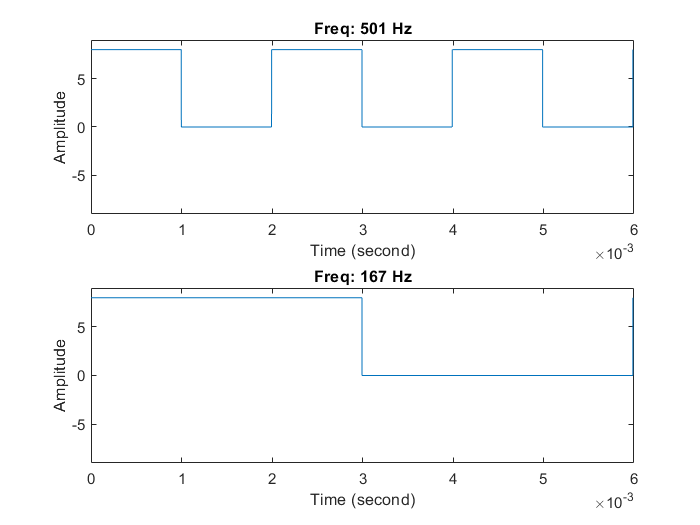

T1 = 2;
T2 = 6;
T12 = lcm(T1, T2) * Tunit;
T1 = T1 * Tunit;
T2 = T2 * Tunit;
s1 = @(t) signal4(A, T1, t);
s2 = @(t) signal4(A, T2, t);
t = 0:Ts:T12;
subplot(2, 1, 1); plot(t, s1(t));
ylim([-A-1, A+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("Freq: %.0f Hz", 1/T1));
subplot(2, 1, 2); plot(t, s2(t)); 
ylim([-A-1, A+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("Freq: %.0f Hz", 1/T2));

inner_product = integral(@(t) s1(t) .* s2(t), 0, T12)

inner_product = 0.1277

#### Orthogonality Tests 2: Sine Wave

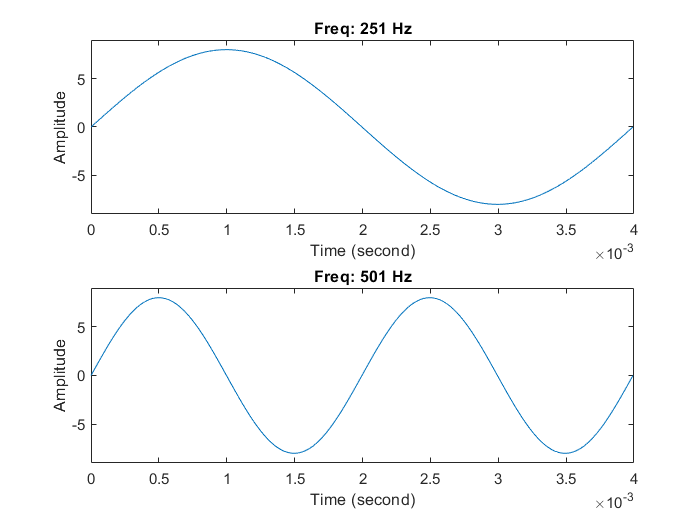

T1 = 4;
T2 = 2;
T12 = lcm(T1, T2) * Tunit;
T1 = T1 * Tunit;
T2 = T2 * Tunit;
s1 = @(t) signal1(A, T1, t);
s2 = @(t) signal1(A, T2, t);
t = 0:Ts:T12;
subplot(2, 1, 1); plot(t, s1(t));
ylim([-A-1, A+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("Freq: %.0f Hz", 1/T1));
subplot(2, 1, 2); plot(t, s2(t)); 
ylim([-A-1, A+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("Freq: %.0f Hz", 1/T2));

inner_product = integral(@(t) s1(t) .* s2(t), 0, T12)

inner_product = 2.4611e-17

### Section 04

#### Finding Orthogonal Basis

For every set of signals, it is possible to find orthogonal basis functions. The maximum number of orthogonal basis functions that can be found is less than or equal to the total number of signals.


$$S=\;\left\lbrace s_1 \left(t\right),\;s_2 \left(t\right),\;s_3 \left(t\right),\;\ldotp \ldotp \ldotp ,s_n \left(t\right)\right\rbrace \;\;\;\Longrightarrow \;\;\phi =\;\left\lbrace \varphi_1 \left(t\right),\;\varphi_2 \left(t\right),\;\varphi_3 \left(t\right),\;\ldotp \ldotp \ldotp ,\varphi_m \left(t\right)\right\rbrace \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;m\le n$$


Gram-Schmidt algorithm is used to extract orthonormal basis functions $\varphi_i \left(t\right)$ from the signals $s_i \left(t\right)$.


$$\mathrm{Signal}\;\mathrm{Space}\;\left(S\right)\;\;\;\;\Longrightarrow^{\mathrm{Gram}-\mathrm{Schmidt}} \;\;\;\mathrm{Orthogonal}\;\mathrm{Basis}\;\mathrm{Functions}\;\left(\phi \right)$$


Gram-Schmidt algorithem can be run recursively on the signal space to construct the orthogonal function space. Here, we will discuss a simple case of two signals. This can be extended to the case involving more signals.


$$\begin{array}{l}
s_1 \left(t\right)={s_{11} \varphi }_1 \left(t\right)+{s_{12} \varphi }_2 \left(t\right)=\left\langle s_1 \left(t\right),\varphi_1 \left(t\right)\right\rangle \varphi_1 \left(t\right)+\left\langle s_1 \left(t\right),\varphi_2 \left(t\right)\right\rangle \varphi_2 \left(t\right)\\
s_2 \left(t\right)={s_{21} \varphi }_1 \left(t\right)+{s_{22} \varphi }_2 \left(t\right)=\left\langle s_2 \left(t\right),\varphi_1 \left(t\right)\right\rangle \varphi_1 \left(t\right)+\left\langle s_2 \left(t\right),\varphi_2 \left(t\right)\right\rangle \varphi_2 \left(t\right)
\end{array}$$


Denote $E_1 =\left\langle s_1 \left(t\right),s_1 \left(t\right)\right\rangle$ and $E_2 =\left\langle s_2 \left(t\right),s_2 \left(t\right)\right\rangle$ as the energy of signals $s_1 \left(t\right)$ and $s_2 \left(t\right)$, respectively. 

The coefficients $s_{ij}$ are determined as follows:


$$\rho =\frac{1}{\sqrt{E_1 E_2 }}\left\langle s_1 \left(t\right),s_2 \left(t\right)\right\rangle$$



$$s_{11} =\sqrt{E_1 }$$
                           
$$s_{12} =0$$



$$s_{21} =\rho \sqrt{E_2 }$$
                        
$$s_{22} =\sqrt{\left(1-\rho^2 \right)E_2 }$$


And the orthonormal functions are defined as follows:


$$\varphi_1 \left(t\right)\;=\frac{1}{\sqrt{E_1 }}s_1 \left(t\right)$$
               
$$\phi_2 \left(t\right)\;=\frac{1}{\sqrt{\left(1-\rho^2 \right)}}\left(\frac{s_2 \left(t\right)}{\sqrt{E_2 }}-\frac{\rho \;s_1 \left(t\right)}{\sqrt{E_1 }}\right)$$


### Section 05

#### Orthonormal Signals from Different Signal Shapes with Similar Frequencies

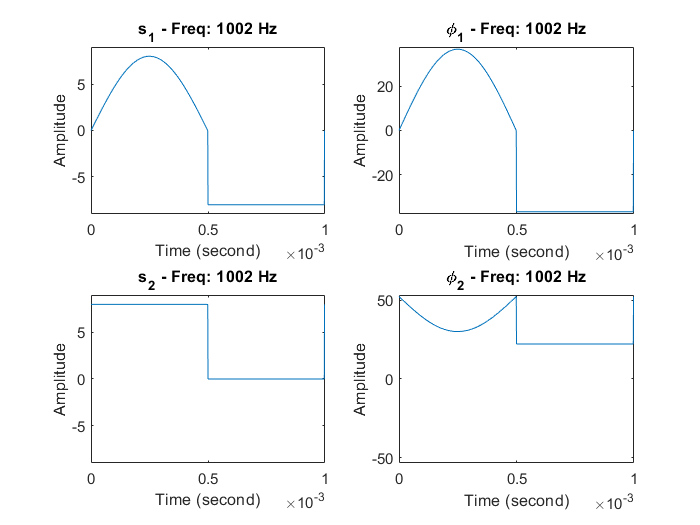

Tb = Tunit;
s1 = @(t) signal2(A, Tb, t);
s2 = @(t) signal4(A, Tb, t);
E1 = integral(@(t) s1(t).^2, 0, Tb);
E2 = integral(@(t) s2(t).^2, 0, Tb);
rho = (1 / sqrt(E1 * E2)) * integral(@(t) s1(t) .* s2(t), 0, Tb);
s11 = sqrt(E1);
s12 = 0;
s21 = rho * sqrt(E2);
s22 = sqrt((1 - rho.^2) * E2);
phi1 = @(t) (1 / sqrt(E1)) * s1(t);
phi2 = @(t) (1 / sqrt(1-rho.^2)) * ( s2(t)/sqrt(E2) - rho.*s1(t)/sqrt(E1) );
figure()
if abs(rho) == 1
    phi2 = @(t) zeros(size(t));
end
t = 0:Ts:Tb;
subplot(2, 2, 1); plot(t, s1(t));
ylim([-max(abs(s1(t)))-1, max(abs(s1(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("s_1 - Freq: %.0f Hz", 1/Tb));
subplot(2, 2, 3); plot(t, s2(t));
ylim([-max(abs(s2(t)))-1, max(abs(s2(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("s_2 - Freq: %.0f Hz", 1/Tb));
subplot(2, 2, 2); plot(t, phi1(t));
ylim([-max(abs(phi1(t)))-1, max(abs(phi1(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("\\phi_1 - Freq: %.0f Hz", 1/Tb));
subplot(2, 2, 4); plot(t, phi2(t));
ylim([-max(abs(phi2(t)))-1, max(abs(phi2(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("\\phi_2 - Freq: %.0f Hz", 1/Tb));

E1, E2, rho, s11, s12, s21, s22

E1 = 0.0479

E2 = 0.0319

rho = 0.5198

s11 = 0.2189

s12 = 0

s21 = 0.0929

s22 = 0.1527

% Orthonormality test
inner_phi1_phi1 = integral(@(t) phi1(t) .* phi1(t), 0, Tb);
inner_phi2_phi2 = integral(@(t) phi2(t) .* phi2(t), 0, Tb);
inner_phi1_phi2 = integral(@(t) phi1(t) .* phi2(t), 0, Tb);
inner_phi1_phi1, inner_phi2_phi2, inner_phi1_phi2

inner_phi1_phi1 = 1.0000

inner_phi2_phi2 = 1

inner_phi1_phi2 = 7.6328e-17

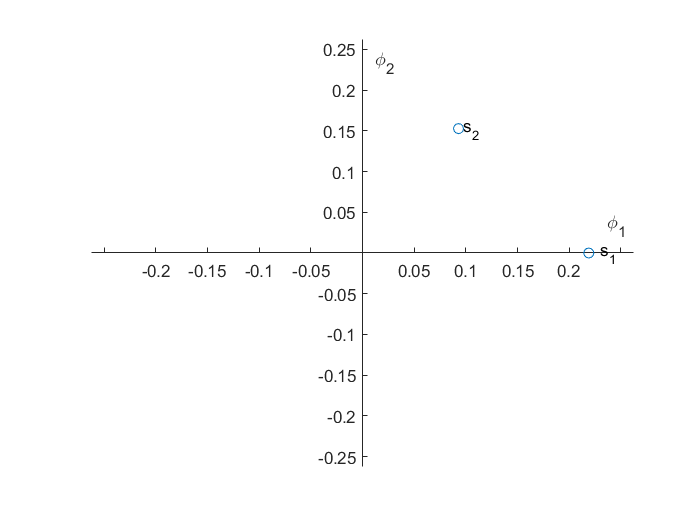

% Geometrical veiw
figure()
S = [s11, s12; s21, s22];
scatter(S(:, 1), S(:, 2), 'o');
text(S(:, 1)*1.05, S(:, 2)*1.00, cellstr(['s_1'; 's_2']))
xlabel('\phi_1'); ylabel('\phi_2')
m = 1.2 * max(max(abs(S)));
xlim([-m, m]); ylim([-m, m]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

### Section 06

#### Orthonormal Signals from Similar or Different Signal Shapes with Different Frequencies

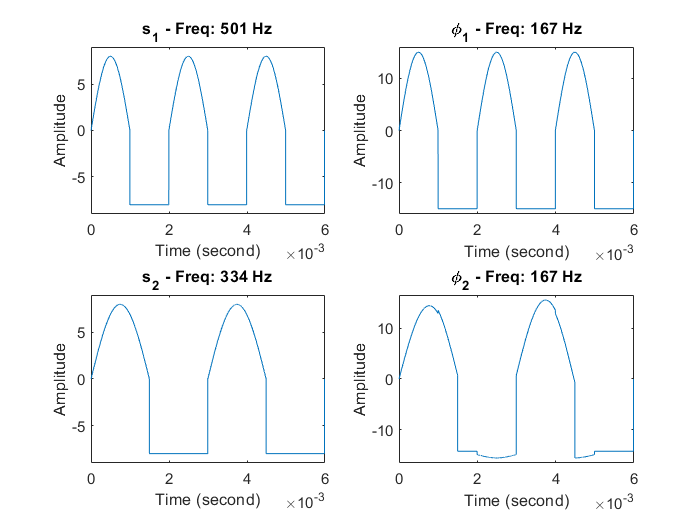

T1 = 2* Tunit;
s1 = @(t) signal2(A, T1, t);
T2 = 3 * Tunit;
s2 = @(t) signal2(A, T2, t);
T12 = lcm(T1/Tunit, T2/Tunit) * Tunit;
E1 = integral(@(t) s1(t).^2, 0, T12);
E2 = integral(@(t) s2(t).^2, 0, T12);
rho = (1 / sqrt(E1 * E2)) * integral(@(t) s1(t) .* s2(t), 0, T12);
s11 = sqrt(E1);
s12 = 0;
s21 = rho * sqrt(E2);
s22 = sqrt((1 - rho.^2) * E2);
phi1 = @(t) (1 / sqrt(E1)) * s1(t);
phi2 = @(t) (1 / sqrt(1-rho.^2)) * ( s2(t)/sqrt(E2) - rho.*s1(t)/sqrt(E1) );
figure()
if abs(rho) == 1
    phi2 = @(t) zeros(size(t));
end
t = 0:Ts:T12;
subplot(2, 2, 1); plot(t, s1(t));
ylim([-max(abs(s1(t)))-1, max(abs(s1(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("s_1 - Freq: %.0f Hz", 1/T1));
subplot(2, 2, 3); plot(t, s2(t));
ylim([-max(abs(s2(t)))-1, max(abs(s2(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("s_2 - Freq: %.0f Hz", 1/T2));
subplot(2, 2, 2); plot(t, phi1(t));
ylim([-max(abs(phi1(t)))-1, max(abs(phi1(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("\\phi_1 - Freq: %.0f Hz", 1/T12));
subplot(2, 2, 4); plot(t, phi2(t));
ylim([-max(abs(phi2(t)))-1, max(abs(phi2(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("\\phi_2 - Freq: %.0f Hz", 1/T12));

E1, E2, rho, s11, s12, s21, s22

E1 = 0.2874

E2 = 0.2874

rho = 0.0446

s11 = 0.5361

s12 = 0

s21 = 0.0239

s22 = 0.5356

% Orthonormality test
inner_phi1_phi1 = integral(@(t) phi1(t) .* phi1(t), 0, T12);
inner_phi2_phi2 = integral(@(t) phi2(t) .* phi2(t), 0, T12);
inner_phi1_phi2 = integral(@(t) phi1(t) .* phi2(t), 0, T12);
inner_phi1_phi1, inner_phi2_phi2, inner_phi1_phi2

inner_phi1_phi1 = 1.0000

inner_phi2_phi2 = 1.0000

inner_phi1_phi2 = 1.1786e-08

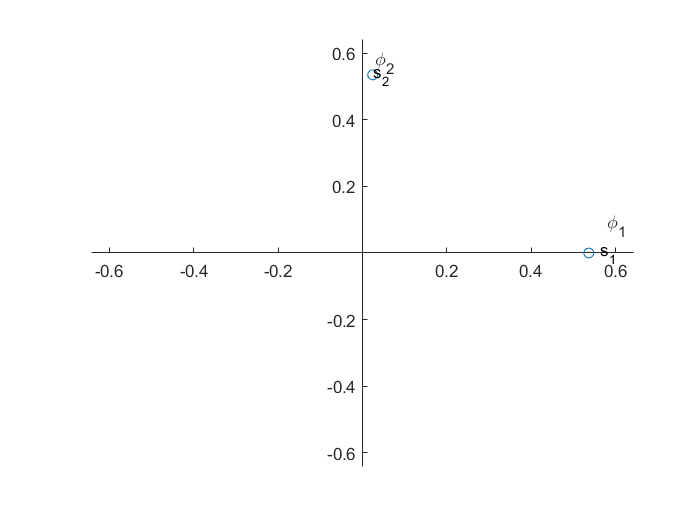

% Geometrical veiw
figure()
S = [s11, s12; s21, s22];
scatter(S(:, 1), S(:, 2), 'o');
text(S(:, 1)*1.05, S(:, 2)*1.00, cellstr(['s_1'; 's_2']))
xlabel('\phi_1'); ylabel('\phi_2')
m = 1.2 * max(max(abs(S)));
xlim([-m, m]); ylim([-m, m]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

### Section 07

#### Orthonormal Signals from Similar Signals with Different Phases

It is possible to use two signals with same frequency but different phase to make the orthonormal basis.

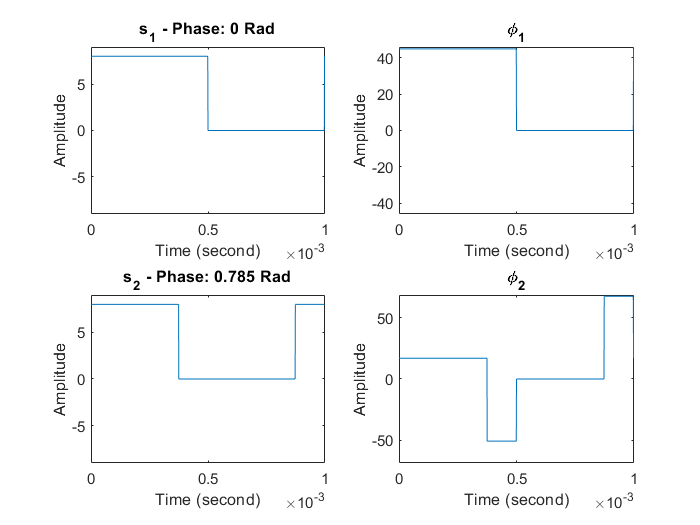

Tb = Tunit;
s1 = @(t) signal4(A, Tb, t);
phase1 = 0.25*Tb/2;
s2 = @(t) s1(t+phase1);
E1 = integral(@(t) s1(t).^2, 0, Tb);
E2 = integral(@(t) s2(t).^2, 0, Tb);
rho = (1 / sqrt(E1 * E2)) * integral(@(t) s1(t) .* s2(t), 0, Tb);
s11 = sqrt(E1);
s12 = 0;
s21 = rho * sqrt(E2);
s22 = sqrt((1 - rho.^2) * E2);
phi1 = @(t) (1 / sqrt(E1)) * s1(t);
phi2 = @(t) (1 / sqrt(1-rho.^2)) * ( s2(t)/sqrt(E2) - rho.*s1(t)/sqrt(E1) );
figure()
if (abs(rho)) == 1
    phi2 = @(t) zeros(size(t));
end
t = 0:Ts:Tb;
subplot(2, 2, 1); plot(t, s1(t));
ylim([-max(abs(s1(t)))-1, max(abs(s1(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("s_1 - Phase: %.0f Rad", 0.0));
subplot(2, 2, 3); plot(t, s2(t));
ylim([-max(abs(s2(t)))-1, max(abs(s2(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title(compose("s_2 - Phase: %.3f Rad", phase1*2*pi/Tb));
subplot(2, 2, 2); plot(t, phi1(t));
ylim([-max(abs(phi1(t)))-1, max(abs(phi1(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title('\phi_1');
subplot(2, 2, 4); plot(t, phi2(t));
ylim([-max(abs(phi2(t)))-1, max(abs(phi2(t)))+1]); xlabel('Time (second)'); ylabel('Amplitude'); title('\phi_2');

E1, E2, rho, s11, s12, s21, s22

E1 = 0.0319

E2 = 0.0319

rho = 0.7500

s11 = 0.1787

s12 = 0

s21 = 0.1340

s22 = 0.1182

% Orthonormality test
inner_phi1_phi1 = integral(@(t) phi1(t) .* phi1(t), 0, Tb);
inner_phi2_phi2 = integral(@(t) phi2(t) .* phi2(t), 0, Tb);
inner_phi1_phi2 = integral(@(t) phi1(t) .* phi2(t), 0, Tb);
inner_phi1_phi1, inner_phi2_phi2, inner_phi1_phi2

inner_phi1_phi1 = 1.0000

inner_phi2_phi2 = 1.0000

inner_phi1_phi2 = 4.4485e-07

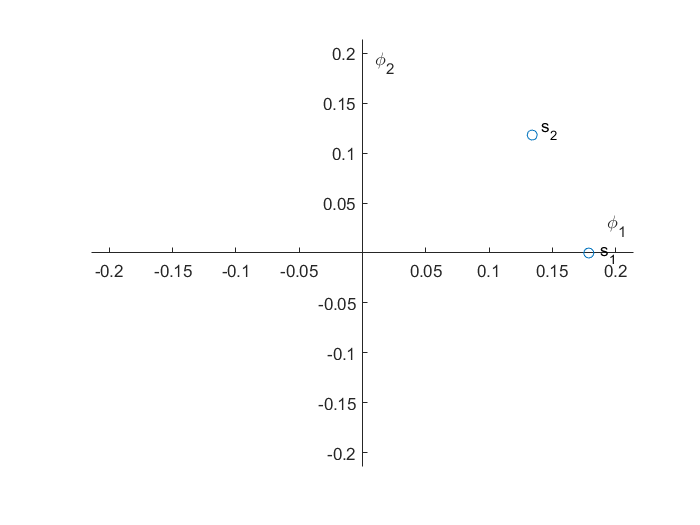

% Geometrical veiw
figure()
S = [s11, s12; s21, s22];
scatter(S(:, 1), S(:, 2), 'o');
text(S(:, 1)*1.05, S(:, 2)*1.05, cellstr(['s_1'; 's_2']))
xlabel('\phi_1'); ylabel('\phi_2')
m = 1.2 * max(max(abs(S)));
xlim([-m, m]); ylim([-m, m]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

As it can be seen, the shape of orhonormal signals does not change when the phase shifts.

### Functions Definition

Simple sinusoid:

function s = signal1(A, T, t)
    t = mod(t, T);
    s = A * sin(2 .* pi .* t / T);
end

Half wave sinusoid:

function s = signal2(A, T, t) %q(t)
    t = mod(t, T);
    s = A * sin(2 .* pi .* t / T);
    s(t > T/2) = -A;
end

Non-linear sinusoid:

function s = signal3(A, T, t)
    t = mod(t, T);
    s = A * sin(2 .* pi .* t ./ T);
    s((s > -A/2) & (s < A/2)) = 0;
end

Pulse:

function s = signal4(A, T, t) %p(t)
    t = mod(t, T);
    s = 0 .* t;
    s(t <= T/2) = A;
    %s(t > T/2 ) = -A;
    s(t > T/2 ) = 0;
end

Triangle Wave:

Note: How the lines equations have been found?

function s = signal5(A, T, t)
    t = mod(t, T);
    s = 0 .* t;
    s(t <= T/4) = 4 * A / T * t(t <= T/4);
    s((T/4 < t) & (t < 3*T/4)) = -4 * A / T * (t((T/4 < t) & (t < 3*T/4)) - T/2);
    s(3*T/4 <= t ) = 4 * A / T * (t(3*T/4 <= t ) - T);
end

Reconstruction:

function s = reconstruct(an, bn, f, n, t)
    s = 0.5 * an(0);
    for nc = 1:(n-1)
        s = s + an(nc) * cos(2 * pi * f .* nc .* t) + bn(nc) * sin(2 * pi * f .* nc .* t);
    end
end